# Create a neural network controller for the robot arm

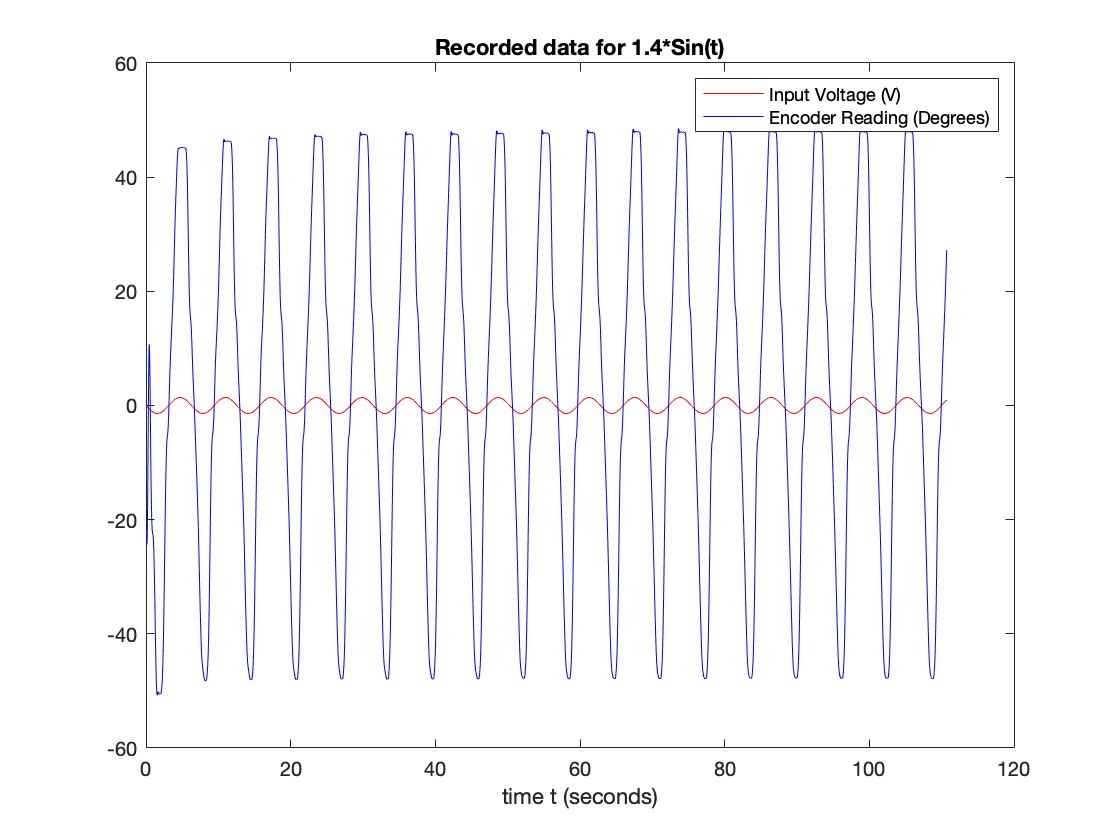

clear
close all
% Load input (Desired angle)
load('input_signal_sin1.4.mat');
in = input_voltage_readings(2,:);
% Load output (Voltage)
load('encoder_reading_sin1.4.mat');
out = encoder_readings(2,:);
time=input_voltage_readings(1,:);
plot(time,in,'r-')
hold on
plot(time,out-24.5,'b-')
legend('Input Voltage (V)','Encoder Reading (Degrees)')
title("Recorded data for 1.4*Sin(t)")
xlabel("time t (seconds)")



% first row of each variable is the time (Ts = 0.02 seconds)

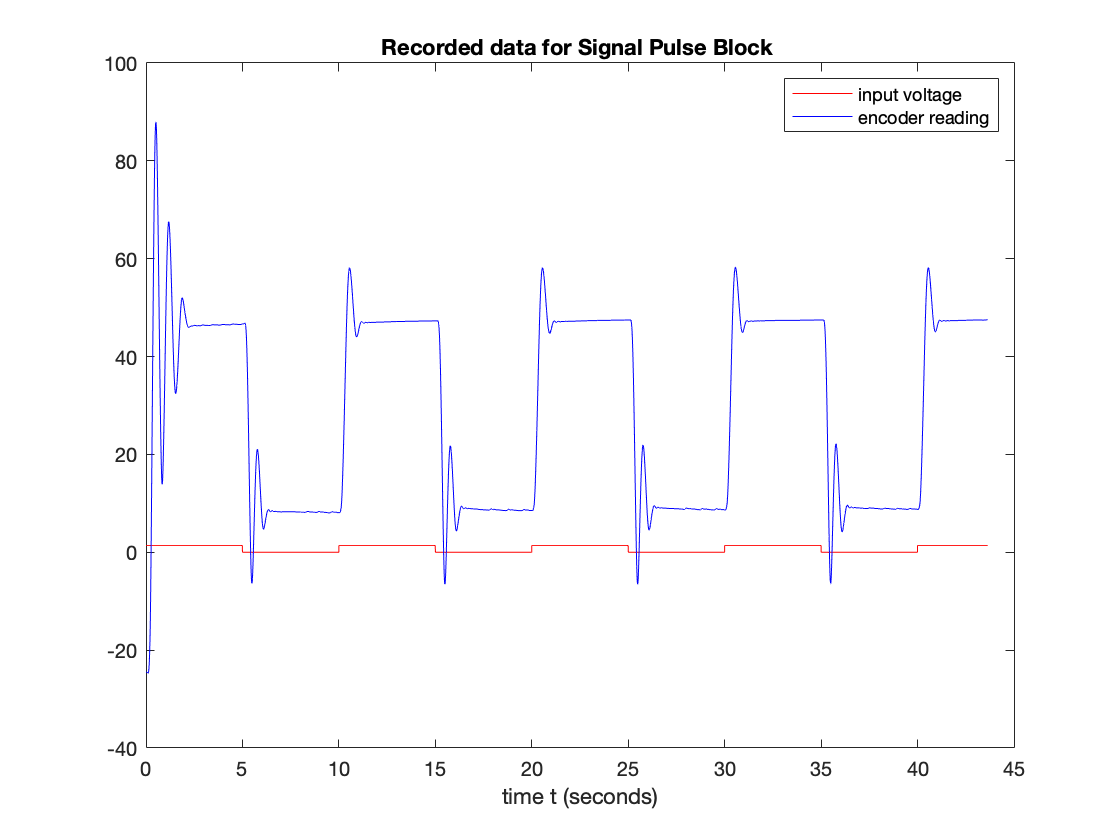

%Load pulse data (you may wish to train the network with this data instead
close all
load('input_signalpulse1.41050.mat');
pulsein = input_voltage_readings(2,:);
% Load output (Voltage)
load('encoder_reading_pulse1.41050.mat');
pulseout = encoder_readings(2,:);
pulsetime=input_voltage_readings(1,:);
figure()
plot(pulsetime,pulsein,'r-')
hold on
plot(pulsetime,pulseout-24.5,'b-')
legend('input voltage','encoder reading')
title("Recorded data for Signal Pulse Block ")
xlabel("time t (seconds)")

## Define size of layers of a feedforwardnet

net = feedforwardnet([5 5 5],'trainbr');
% Remove processing functions
% net.inputs{1}.processFcns = {};
% net.outputs{1}.processFcns = {};
% Determine the size of inputs and outputs and activation functions
net.inputs{1}.size = 1; % size of inputs
net.layers{4}.size = 1; %size of outputs
net.layers{1}.transferFcn = 'tansig'; % poslin = relu
net.layers{2}.transferFcn = 'tansig'; % tansig = tanh
net.layers{3}.transferFcn = 'purelin'; % purelin = linear
% Define the initilization of values in each layer and overall network
net.initFcn = 'initlay';
net.layers{1}.initFcn = 'initnw';
net.layers{2}.initFcn = 'initnw';
net.layers{3}.initFcn = 'initnw';

## Train the network

net = init(net);
net = train(net,out,in);
y = net(out); 

mse = sum(abs(y.^2 - in.^2))/(length(in))

mse = 0.2609

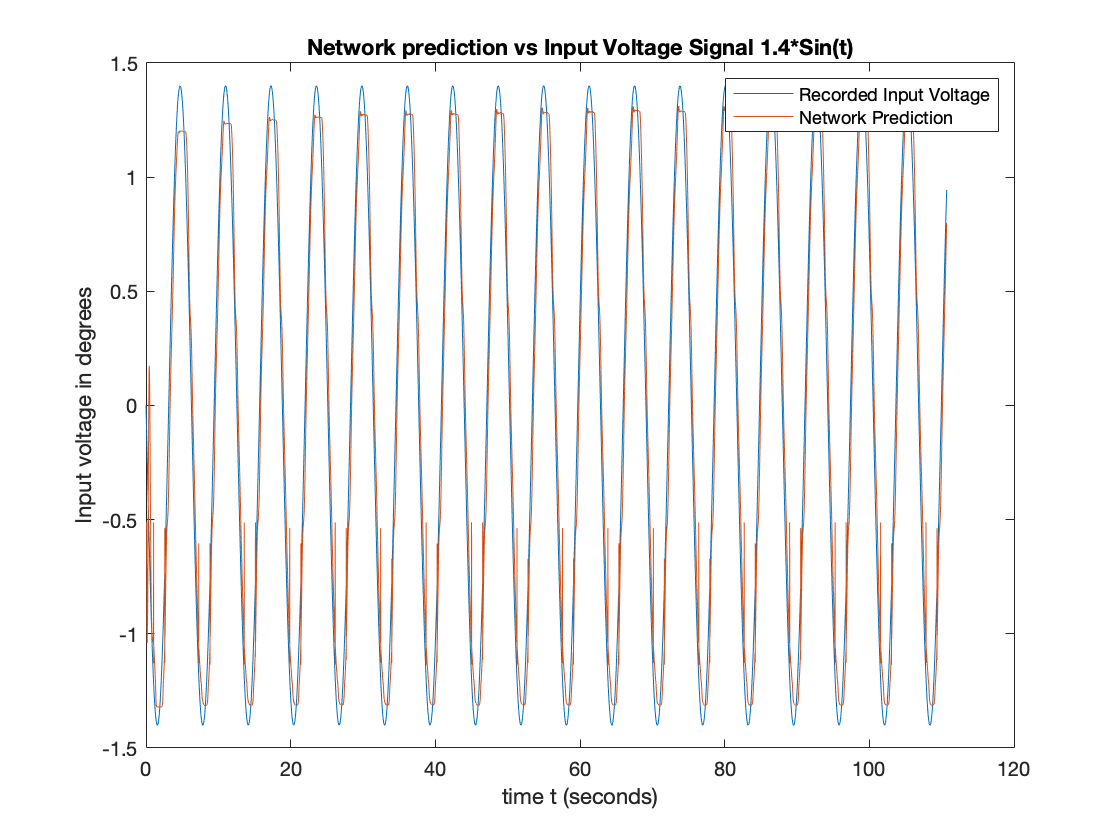

figure()
plot(time,in)
hold on;
plot(time,y)
hold off;
title("Network prediction vs Input Voltage Signal 1.4*Sin(t)")
xlabel("time t (seconds)")
ylabel("Input voltage in degrees")
legend('Recorded Input Voltage', 'Network Prediction')

## Test the network

Load input (Desired angle)

close all
load('input_signal_repeating_sequence.mat');
intest = input_voltage_readings(2,:);
% Load output (Voltage)
load('encoder_reading_repeating_sequence.mat');
% Load output (Voltage)
outtest=encoder_readings(2,:)

outtest =          0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0    0.0439    0.0439    0.0439    0.0439    0.0439    0.0879    0.0879    0.0879    0.1318    0.1318    0.1758    0.1758    0.2197    0.2197    0.2637    0.3076


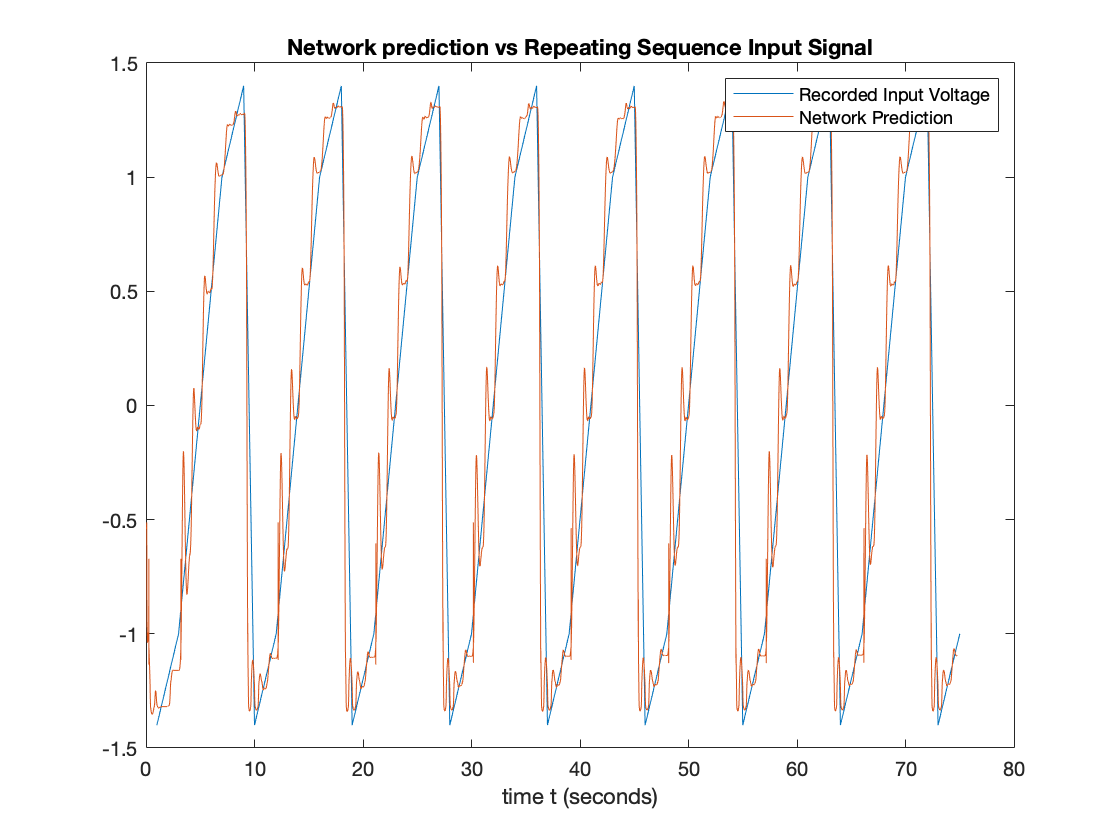

y = net(outtest); 

%mse = sum(abs(y.^2 - intest.^2))/(length(intest))

plot(intest)
hold on
plot(encoder_readings(1,:),y)
legend('Recorded Input Voltage','Network Prediction')
title("Network prediction vs Repeating Sequence Input Signal")
xlabel("time t (seconds)")

## Save network and generate simulink model

%generate simulink block of net

gensim(net)